# Pose Data

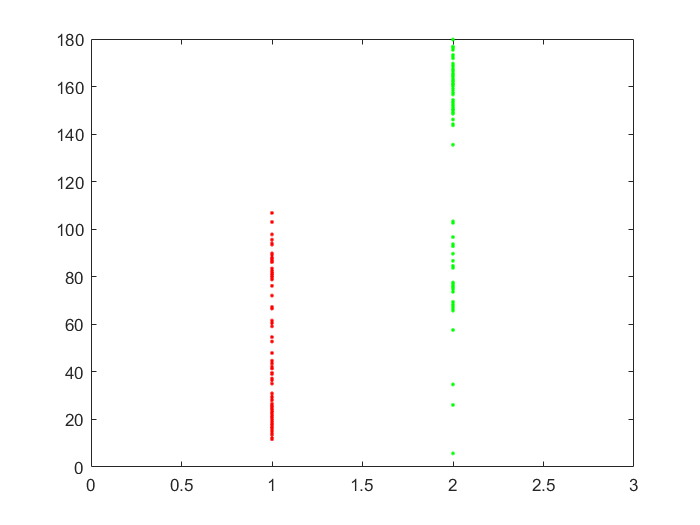

data_pose = load("pose_theta_data.txt");
n = length(data_pose);
plot(ones(n) * 1, data_pose(:, 1), '.r');
hold on
plot(ones(n) * 2, data_pose(:, 2), '.g');
xlim([0, 3]);
hold off

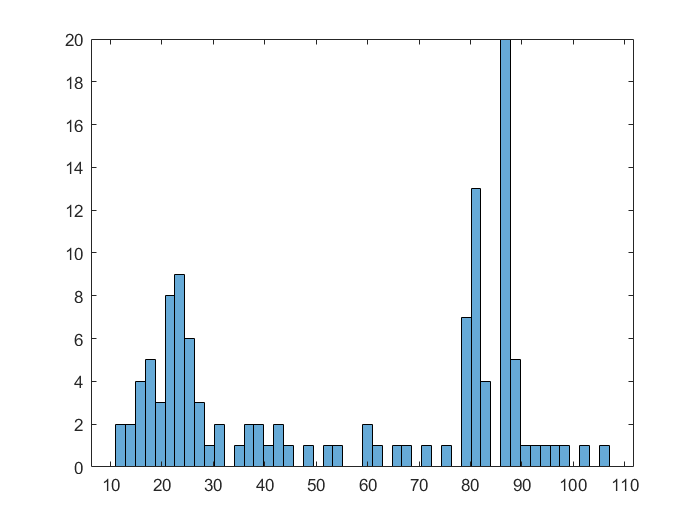

histogram(data_pose(:, 1), 50)

# Hands Data

data_hands0 = load("hands_theta_data0.txt");
data_hands1 = load("hands_theta_data1.txt");
data_hands2 = load("hands_theta_data2.txt");


## figure 1

     1



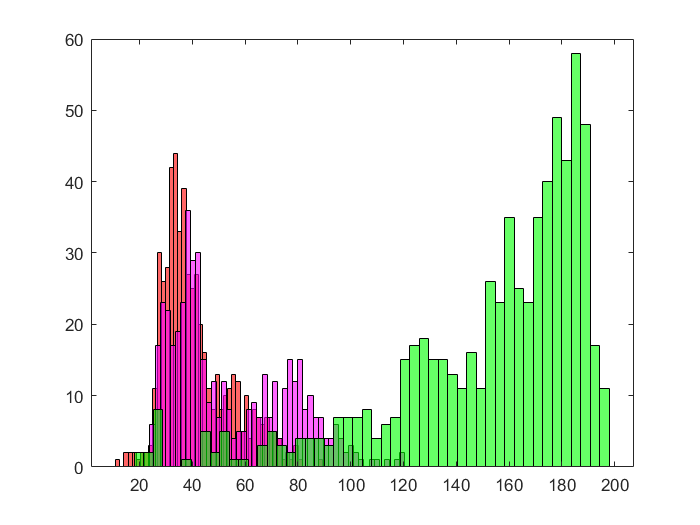

     2



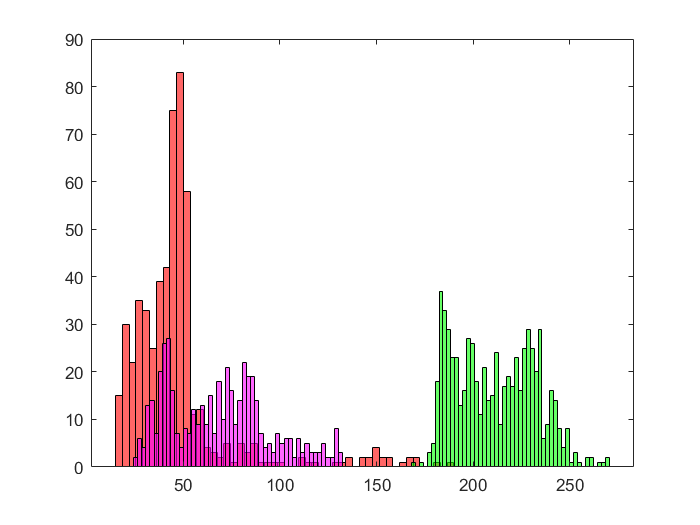

     3



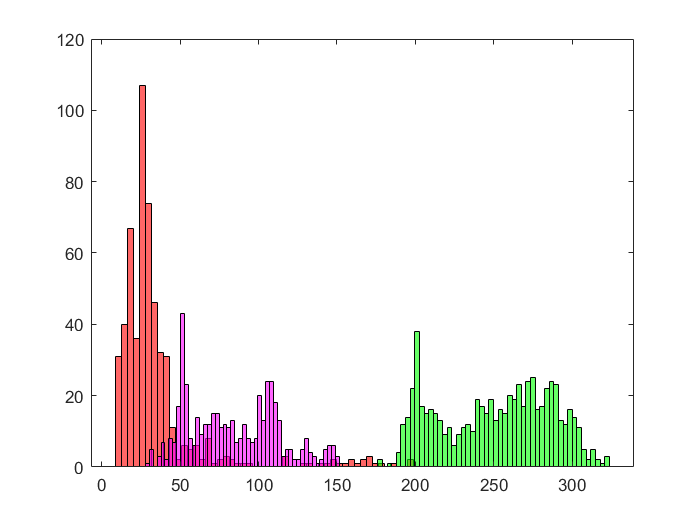

     4



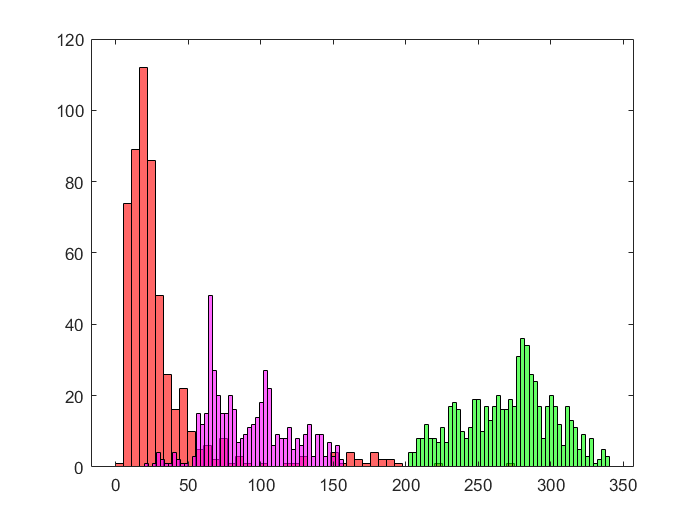

     5



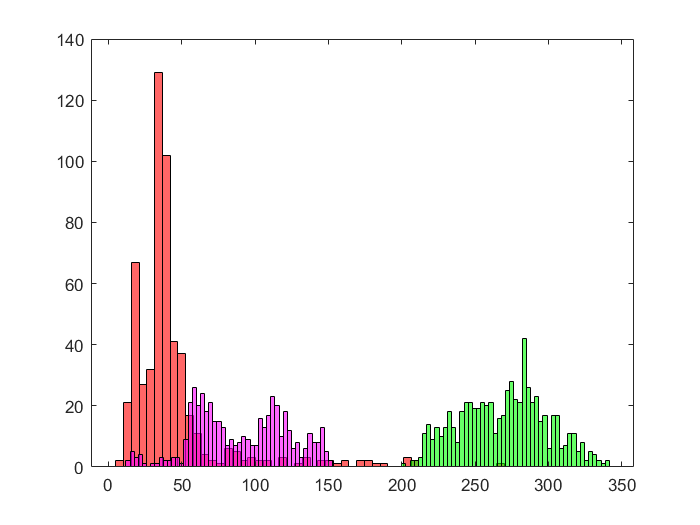

n_bin = 50;
for idx_fig = 1:5
    disp(idx_fig)
    figure
    histogram(data_hands0(:, idx_fig), n_bin, "FaceColor","r")
    hold on
    histogram(data_hands1(:, idx_fig), n_bin, 'FaceColor', 'magenta')
    hold on
    histogram(data_hands2(:, idx_fig), n_bin, 'FaceColor',"g")
end

# 工程经济学测试

syms r;
m = 11

m = 11

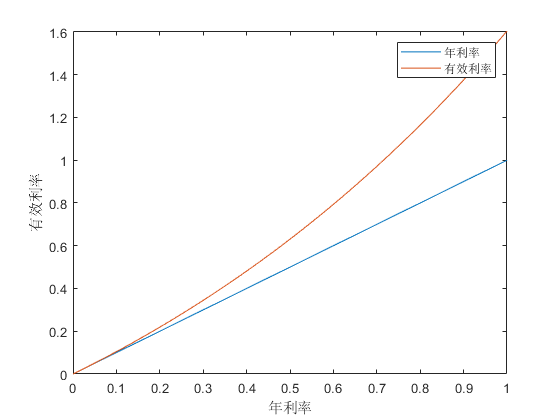

f = (1 + r/m)^m - 1;
figure 
hold off
fplot(r, [0.000001, 0.999999])
hold on
fplot(f, [0.000001, 0.999999])
legend("年利率", '有效利率')
xlabel("年利率")
ylabel('有效利率')